# Modelo de Ball&Beam y Control PID digital

Departamento de Electrónica - Universidad de Nariño

Yo, Control por computador

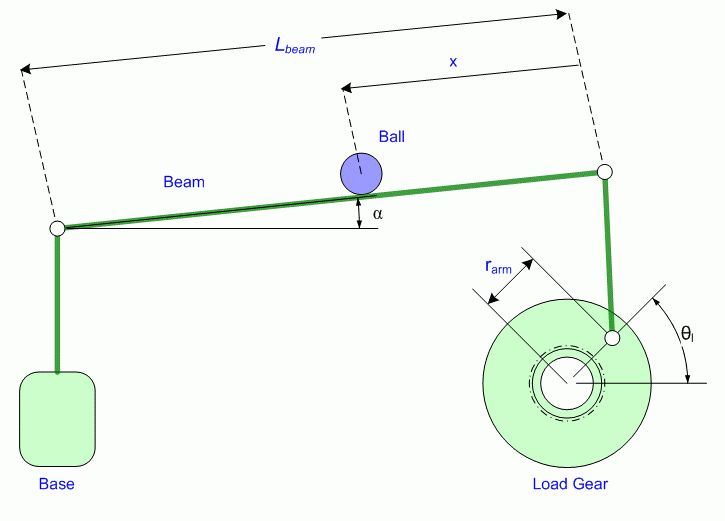

#### Parámetros

Definición de Parámetros (en unidades del SI)

### Diseño de controlador PID

Simbolicos

clear; close all; clc;
sympref('FloatingPointOutput',false);

Parámetros

%%%% Parametros
r_arm=0.0254; L_beam=0.4255; g=9.8;
y_ref=0.2;

%%%% Variables Auxiliares
kbb=5*g*r_arm/(7*L_beam);

Sistema Linealizado

%%% Matrices del sistema lineal en continuo
A=[0 1;0 0];
B=[0;kbb];
C=[1 0];
D=0;
Sys1c=ss(A,B,C,D)

Sys1c =
 
  A = 
       x1  x2
   x1   0   1
   x2   0   0
 
  B = 
           u1
   x1       0
   x2  0.4179
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


TF1=tf(Sys1c)

TF1 =
 
  0.4179
  ------
   s^2
 
Continuous-time transfer function.
Model Properties



%%% Matrices del sistema lineal en discreto
Ts=0.2;
Sys1dg=c2d(Sys1c,Ts,'zoh');
Adg=Sys1dg.A

Adg =     1.0000    0.2000
         0    1.0000


Bdg=Sys1dg.B

Bdg =     0.0084
    0.0836


Cdg=Sys1dg.C;
Ddg=Sys1dg.D;

%%% Sistema Ampliado Discreto
Aa = [Adg zeros(2,1); -C*Adg 1]; 
Ba = [Bdg; -C*Bdg];

Diseño del controlador

%%% StateFB Con Integrador
    %%% Ubicacion de polos Bessel
    % polos = [-4.350+8.918i*1, -4.350-8.918i*1, -5.913*0.5]; % Polo Itae
    polos=[(-3.967+3.785i)*0.3, (-3.967-3.785i)*0.4, -5.009*0.1]  % Polos Bessel

polos =   -1.1901 + 1.1355i  -1.5868 - 1.5140i  -0.5009 + 0.0000i


    polosdg=exp(polos*Ts)

polosdg =    0.7679 + 0.1775i   0.6949 - 0.2171i   0.9047 + 0.0000i


    Ka=acker(Aa,Ba,polosdg)

Ka =     8.6683    6.6383   -0.6235



    % %%% Ubicacion de Polos LQR
    % Qa=diag([0 0 1]);
    % R=1; 
    % Kaa=dlqr(Aa,Ba,Qa,R)
K=Ka;

## Implementación de control con simulación ODE

Condiciones iniciales y periodo de muestreo

Tsim=40;            % Tiempo total de la simulación
Ts=0.2;             % Periodo de muestreo
Ns=round(Tsim/Ts);  % Número de periodos de muestreo que tendrá la simulación.
x_0=[0 0]';         % Condiones Inciales [pos, vel]
m=0;                % Señal de control para el primer instante de muestreo.
int_err=0;
x=zeros(Ns,2); usim=zeros(Ns,1); % Tamaño de vectores definido
ref=0.2;
% Ka=[10, 5, 0.5]

Ciclo de simulación

for i=1:Ns
    [~,xd]=ode45('plantafcn',Ts,x_0,[],kbb,m(1));   % Simular la planta para un Ts.
    xmed=xd(end,:)';  % Medir estados (la última señal se toma a los Ts segundos).
    %%% State Feedback Control
    e_act=1*(ref-xmed(1));  % Cálculo del error
    int_err=int_err+e_act;  % Integrador 2
    m=-(dot(Ka(1:2),xmed))+Ka(end)*int_err; % Señal de control
    
    %%% Actualiza Variables y guarda para graficar
    x_0=xmed; x(i,:)=xmed'; usim(i,:)=m; e_ant=e_act; 
%     if i>round(Tsim/Ts/2)
%         ref=0.4;
%     end
end

Graficación

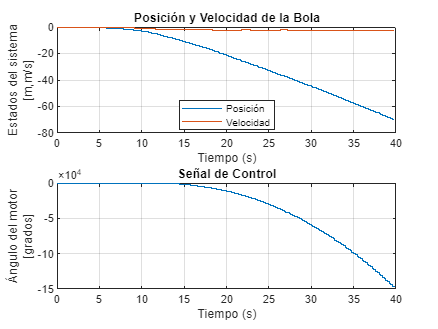

tdisc=0:Ts:Ns*Ts-Ts;
figure; subplot(2,1,1); stairs(tdisc,x); title('Posición y Velocidad de la Bola');
xlabel('Tiempo (s)'); ylabel({'Estados del sistema','[m,m/s]'});
legend('Posición','Velocidad','Location','best')
grid on;
subplot(2,1,2); stairs(tdisc,usim*180/pi); title('Señal de Control');
xlabel('Tiempo (s)'); ylabel({'Ángulo del motor','[grados]'});
grid on;